# Validation of Linear Effects in Fiber Propagation with CSFM

## Background

The Split Step Fourier Method is a numeric method for simulation optical fiber propagation. In this Live Script we validate the effect of attenuation, second order dispersion ($\beta_2$), and third order dispersion ($\beta_3$) though the propagation of a Gaussian Pulse in an optical fiber.

## Theory

The propagation of a Gaussian Pulse in an optical fiber under linear effects has an analytical solution [1][2]. Under the effect of attenuation and second order dispersion, after propagation, the pulse conserves the shape Gaussian, but the power is reduced and suffers temporal broadening, as shown in the next figure:


$$\left|E_{\textrm{in}} \right|=\;\exp \;\left(-\frac{t^2 }{\;2T_0^2 }\right)$$
                                                                      
$$\left|E_{\textrm{out}} \right|=\frac{T_0 }{T_B }\exp \;\left(-\alpha \;L\right)\exp \;\left(-\frac{t^2 }{\;2T_B^2 }\right)$$


    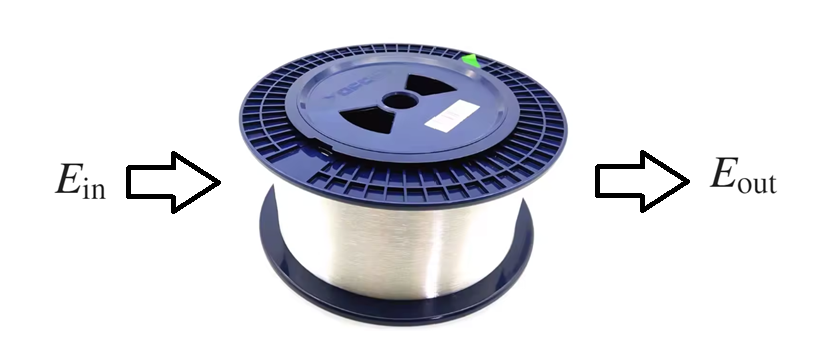

where $\alpha \;$is the attenuation coefficient and $T_0$ is the duration of the input pulse. The broadening factor can be calculated from the link parameters (link length $L_{\textrm{link}}$ and second order dispersion coefficient $\beta_{2\;}$):

 $T_B \;=T_0 \left(\left.\sqrt{\;1+\left(L_{\textrm{link}} \;\beta_{2\;} /\;T_0^2 {\left.\right)}^2 \right.}\right)\right)$ (1)

The Full Width at Half Maximum of the pulse is a more practical magnitude and serves to measure the pulse broadening:


$${\textrm{FWHM}}_{\textrm{out}\;} =2\;\sqrt{\ln \left(2\right)}T_B \;$$


On the other hand, when a Gaussian pulse is affected only by the third order dispersion coefficient ($\beta_3$), analytical formulas por pulse broadening are more complex than the previous case and have more parameters to analyze [2], but still can be determined.

To validate the linear effects caused by dispersion and attenuation, it is proposed the following code tests:

- The propagation of Gaussian Pulses in a fiber with only $\alpha$,$\;\beta_{2\;}$ parameters. The results will be compared against the closed form expressions given in [1].

- The propagation of Gaussian Pulses in a fiber with only $\;\beta_{3\;}$ parameters. The results will be compared against the curves given in [2].

## Script Initialization and Variables:

clear; clc; close all;
set(0,'DefaultAxesFontName','Cambria Math');
set(0,'DefaultAxesFontSize',12);
set(0,'DefaultLineLineWidth',1.5);
addpath('..\lib')

%% Main Parameters
% The simulation parameters are specified below


%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                  Units
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 Units.THz = 1e12;
 Units.GHz = 1e9;
 Units.MHz = 1e6;
 Units.kHz = 1e3;
 Units.km  = 1e3;
 Units.nm  = 1e-9;
 Units.us  = 1e-6;
 Units.ns  = 1e-9;
 Units.mW  = 1e-3;
 Units.nA  = 1e-9;
 Units.ps  = 1e-12;
 Units.fs  = 1e-15;

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                    Signal & simulation parameters
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Bitrate                     = 40/(10*1e-10);         % [Gbps]  
Baudrate                    = Bitrate;               % [Bits]
Ovs_factor                  = 10;                    % [Samples/symbol]
fs                          = Baudrate* Ovs_factor;
N_samples                   = 8000;                  % Total number of samples

% Time and frequency axis
time_vec                    = (0 : 1 : N_samples - 1)/fs;
%% Fiber parameters
cnfg_fiber.fs          = fs;           % Frecuencia de muestreo de la Simulación [Hz]
cnfg_fiber.N_samp      = N_samples;    % Número de muestras de la simulación  
cnfg_fiber.L           = 10;           % Longitud de la fibra [km]
cnfg_fiber.alpha_dB    = 0.23;         % Atenuación [dB/km]
cnfg_fiber.beta_2      = -20;          % Dispersión [ps²/km]
cnfg_fiber.beta_3      = 0.032535;     % Dispersión [ps³/km]
cnfg_fiber.gamma       = 0.1;          % Coeficiente no lineal [(W·km)^-1]
cnfg_fiber.phi_max     = 1e12;         % Máxima rotación de fase [rad] 
cnfg_fiber.en_adaptive = 0;            % Habilita o desabilita metodo de paso adaptivo

disp(' ');

disp(['Length = ' num2str(cnfg_fiber.L)  ' [km]']);

Length = 10 [km]


disp(['Attenuation = ' num2str(cnfg_fiber.alpha_dB) +' [dB/km]'])

Attenuation = 0.23 [dB/km]


disp(['Beta_2 = ' num2str(cnfg_fiber.beta_2) +' [ps^2/km]'])

Beta_2 = -20 [ps^2/km]


fiber_opt_obj = FO_lib(); %Instantiate Fiber Objet


## Generation Of Gaussian Pulses

A Gaussian pulse of T0 = 50 ps in the x polarization axis is generated:

%% Gaussian pulse parameters
T0 = 2/Bitrate;     % Pulse width in s
tau = time_vec; % Time window in s
tau = tau - tau(end)/2;

disp(' ');

disp(['Gaussian Pulse parameter T_0 = ' num2str(2*T0/(Units.ps)) ' ps']);

Gaussian Pulse parameter T_0 = 100 ps



pulse_x = exp(-tau.^2 / (2 * T0^2)); % Gaussian pulse in X

h1 = figure();
plot(tau*1e12, abs(pulse_x).^2 / max(abs(pulse_x).^2),'b');
xlabel('Time [ps]');
ylabel('Normalized Power');
title('X Polarization');
grid on
xlim([-400,400]);

h2 = figure();
plot(tau/(sqrt(8)*T0)*4, pulse_x,'b');
xlabel('Time [ps]');
ylabel('Amplitude [a.u]');
title('X Polarization');
grid on
xlabel('A factor (\propto T_0)');
xlim([-8,8]);
ylim([-0.2,1]);




## Run Simulation for Different Lengths

%% Start Simulation

L_ = (25:12.5:250);    % Fiber length sweep [km]
L3rdD_ = 1/(32*cnfg_fiber.beta_3*(1e-12)^3)*(sqrt(8)*T0)^3 * [1:1:9,10:10:100];    % Fiber length sweep for 3rd Order Disp Test[m]

%Init Parameters
Tfwhm_in = zeros(1,length(L_));
Tfwhm_out = zeros(1,length(L_));
Power_in = zeros(1,length(L_)); 
Power_out = zeros(1,length(L_)); 
At_meas = zeros(1,length(L_));
L_D = zeros(1,length(L_));
FWHM_theo = zeros(1,length(L_));
B = zeros(1,length(L_));
I = zeros(1,length(L_));




for uu = 1:length(L_)

    % Input signal as a 2xN matrix
    signal_in = pulse_x;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %Attenuation and 2nd Order Dispersion Test
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    cnfg_fiber.L          = L_(uu);
    cnfg_fiber.beta_2    = -21.7;
    cnfg_fiber.beta_3    = 0;
    cnfg_fiber.gamma       = 0.0;  
    cnfg_fiber.alpha_dB    = 0.23;
    % Propagation of the pulse through the fiber
    fiber_opt_obj = fiber_opt_obj.Init(cnfg_fiber); %Update configs
    signal_out = fiber_opt_obj.Process(signal_in);
    % Input Pulse FWHM
    Tfwhm_in(uu) = pulsewidth( abs(signal_in(1,:)), tau );
    % Output Pulse FWHM
    % figure;plot(abs(signal_in));hold on;plot(abs(signal_out));hold off
    Tfwhm_out(uu) = pulsewidth( abs(signal_out(1,:))  , tau );  
    Power_in(uu) =  mean( abs(signal_in).^2 );
    Power_out(uu) =  mean( abs(signal_out).^2 );
    
    At_meas(uu) = 10*log10(Power_out(uu)/Power_in(uu));
    
    
    % Visualization of the results
    if mod(L_(uu),50) == 0
        figure(h1)
        hold on;
        plot(tau*1e12, abs(signal_out).^2 / max(abs(signal_out).^2));
    end
    
    L_D = T0^2/(cnfg_fiber.beta_2*(1e-12)^2); %Dispersion Length
    FWHM_theo(uu) = 2*sqrt(log(2)*2)*T0*sqrt(1+(cnfg_fiber.L/L_D)^2); % Predicted FWHM
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Thrid Order Dispersion Test 
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    cnfg_fiber.L         = L3rdD_(uu);
    cnfg_fiber.beta_2    = 0;
    cnfg_fiber.beta_3    = 0.032535;
    cnfg_fiber.alpha_dB = 0;
    % Propagation of the pulse through the fiber
    fiber_opt_obj = fiber_opt_obj.Init(cnfg_fiber); %Update configs
    signal_out = fiber_opt_obj.Process(signal_in);
    
    % Visualization of the results
    if (uu == 1)  || (uu == 5) || (uu == 10) 
        figure(h2)
        hold on
        plot(tau/(sqrt(8)*T0)*4,real(signal_out(1,:)));  %sqrt(8) factor is to match paper vs sim
    end 
    
    B(uu)= 32*(cnfg_fiber.beta_3*(1e-12)^3)*cnfg_fiber.L/(sqrt(8)*T0)^3; %sqrt(8) factor is to match paper vs sim
    I(uu) = max(abs(signal_out(1,:)));

end


## Results

#### Attenuation and 2nd Order Dispersion:

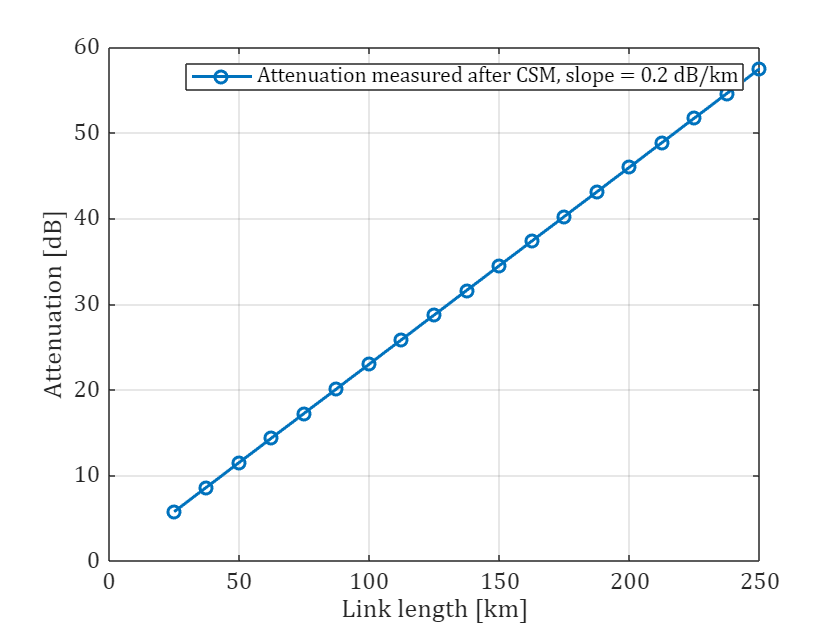

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% RESULTS: Attenuation & 2nd Order Dispersion Test
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Attenuation vs Link length
figure()
plot(L_,-1*At_meas,'-o')
legend('Attenuation measured after CSM, slope = 0.2 dB/km')
xlabel('Link length [km]')
ylabel('Attenuation [dB]')
grid on

Fiber attenuation extracted from simulations matches the asigned value.

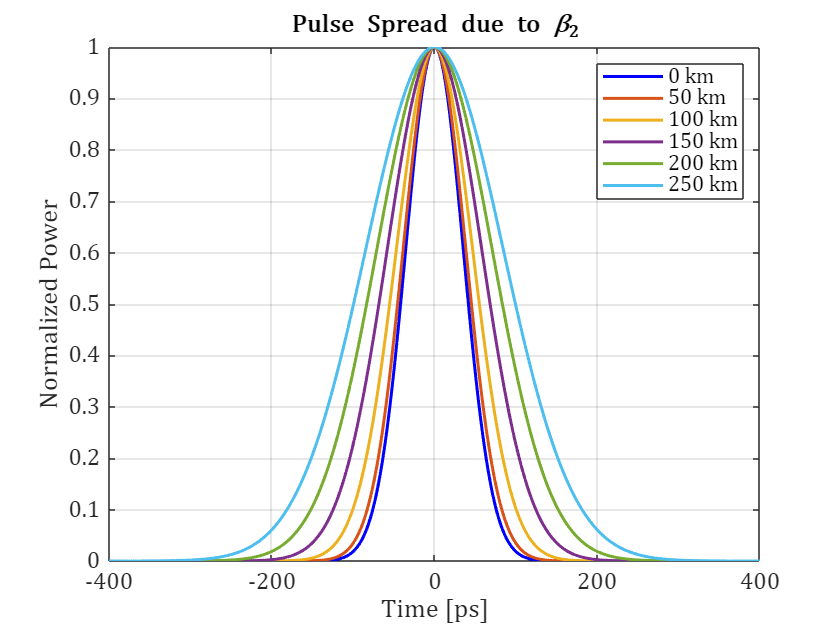

%Pulse Spread due to 2nd order dispersion
figure(h1)
legend('0 km', '50 km', '100 km', '150 km', '200 km', '250 km')
title('Pulse Spread due to \beta_2')


disp(' ');

disp(['FWHM Input Pulse [ps]         = ' num2str(Tfwhm_in(1)/(Units.ps))]);

FWHM Input Pulse [ps]         = 117.7698


disp(['Fiber Lengths [km]            = ' num2str(L_)]);

Fiber Lengths [km]            = 25          37.5            50          62.5            75          87.5           100         112.5           125         137.5           150         162.5           175         187.5           200         212.5           225         237.5           250


disp(['FWHM Output Pulse [ps]        = ' num2str(Tfwhm_out/(Units.ps))]);

FWHM Output Pulse [ps]        = 120.5166      123.8546      128.3816      133.9822      140.5226      147.8736      155.9356      164.5923      173.7552      183.3509       193.316      203.5961      214.1452      224.9248      235.9024       247.051      258.3539       269.789      281.3363


disp(['Theory FWHM Output Pulse [ps] = ' num2str(FWHM_theo/(Units.ps))]);

Theory FWHM Output Pulse [ps] = 120.4813      123.8213      128.3515      133.9511      140.4923      147.8501       155.909       164.566      173.7318        183.33      193.2963      203.5766      214.1256      224.9055      235.8848      247.0368      258.3391      269.7729      281.3222


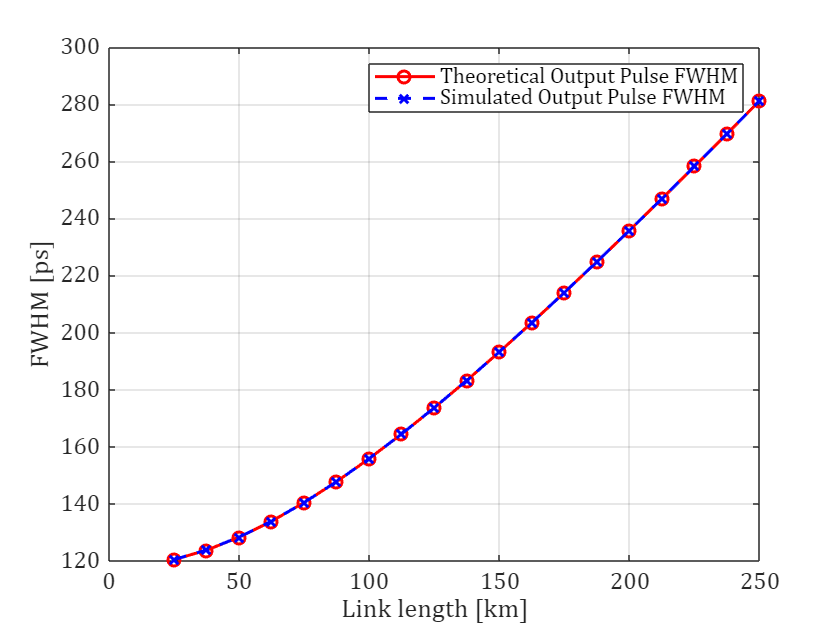


%%% Relative percentage error (relative to theory prediction): 
er_perc = abs(FWHM_theo - Tfwhm_out).^2 ./ FWHM_theo.^2 * 100; % [%]

figure()
plot(L_,FWHM_theo/(Units.ps),'r-o')
hold on
plot(L_,Tfwhm_out/(Units.ps),'b--x')
hold off;
xlabel('Link length [km]')
ylabel('FWHM [ps]')
legend('Theoretical Output Pulse FWHM','Simulated Output Pulse FWHM')
grid on

FWHM results match with FWHM values predicted by Theory with a relative percentage error less than 0.0001 % for all tested conditions.

#### 3rd Order Dispersion:

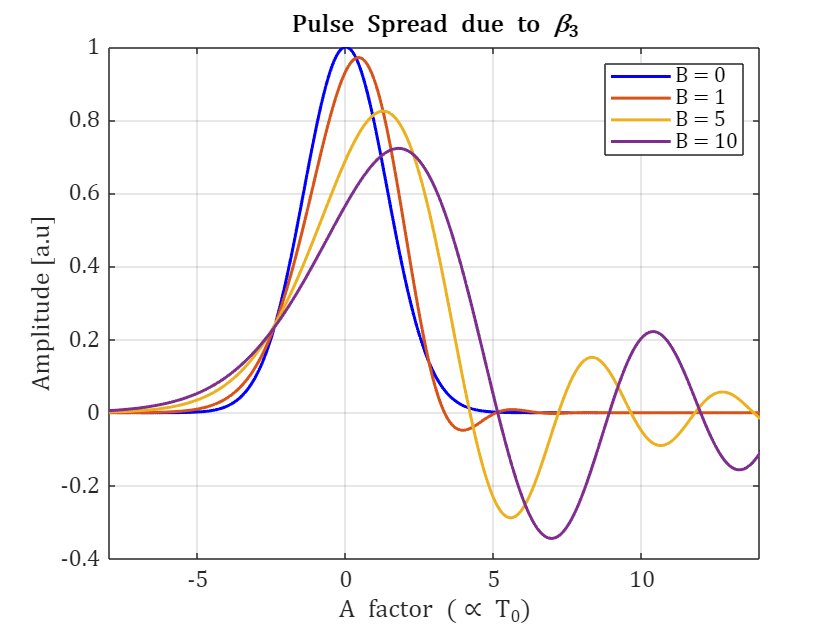

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% RESULTS: Thrid Order Dispersion Test 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(h2)
legend('B = 0', 'B = 1', 'B = 5', 'B = 10')
title('Pulse Spread due to \beta_3')
xlim([-8,14])
ylim([-0.4,1])

                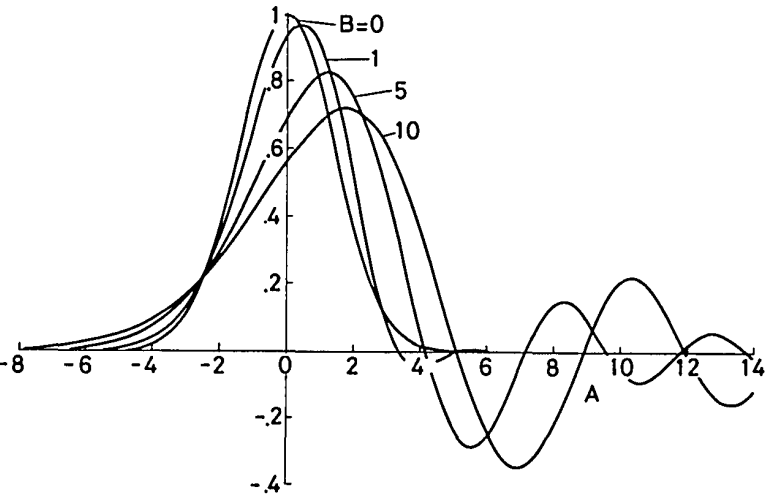

                                                  *Figure extracted from [2].       

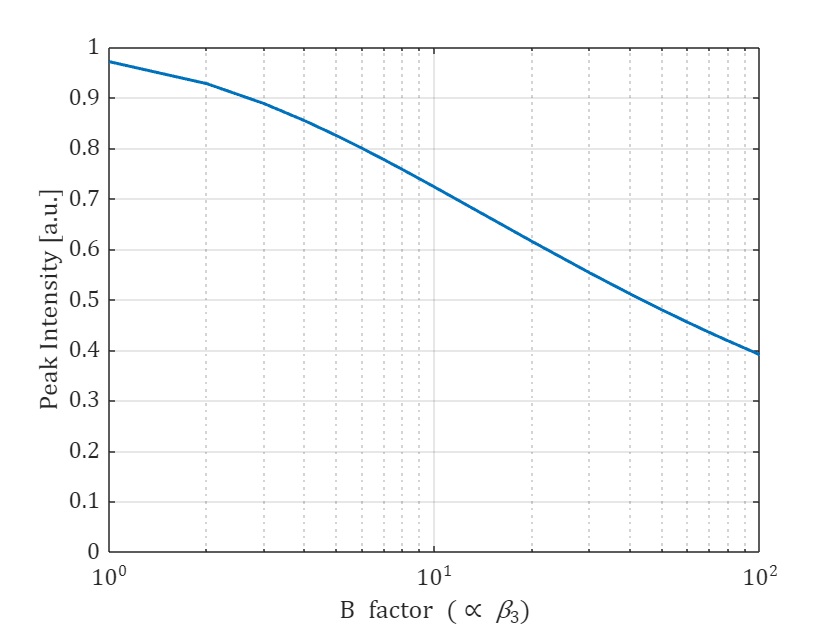

figure();
semilogx(B,I)
xlabel('B factor (\propto \beta_3)')
ylabel("Peak Intensity [a.u.]")
xlim([1,100])
ylim([0,1])
grid on

       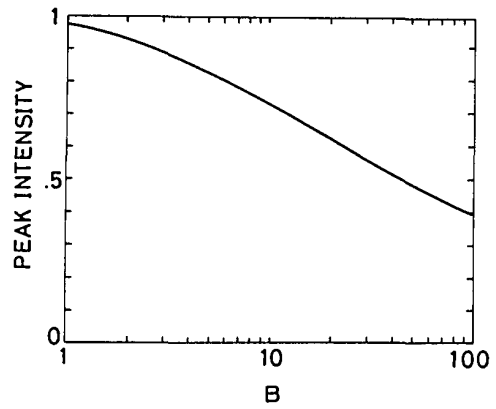

                                                      *Figure extracted from [2].    

Curves obtained from simulation match those in [2].

## Conclusion

The CSFM generates the same results described by Theory when Gaussian pulses are propagated in an optical fiber when linear effects (attenuation and dispersion) are considered.

#### References

[1] G. P. Agrawal, "Nonlinear Fiber Optics", 3rd Edition.

[2] M. Miyagi and S. Nishida, "Pulse spreading in a single-mode fiber due to third-order dispersion", Applied Optics, Vol. 18, No. 5, 1 March 1979.